load('/home/tfpeng/work/other/TFwork/2021/pytools/imudata_array.txt')

% extract oxford data set
imu_data=imu1(:,8:9)
dt=diff(imu1(:,1))
w=imu1(:,7)
w=w(2:end);
imu_data=imu_data(2:end,:)
imudata_array=[dt,imu_data,w]

[m,n]=size(imudata_array);
pos=[0;0;0];
for i =1:m
    temppos=ImuOdm(imudata_array(i,2),imudata_array(i,3),imudata_array(i,4),imudata_array(i,1));
    pos(:,end+1)=temppos;
end
plot(pos(1,:),pos(2,:))

% extract wuhan data set
clearvars -except nav imuraw;
num=100000;
dvz=imuraw(1:num,7);
dt=diff(imuraw(1:num+1,1));
az=dvz./dt;

dtheta=imuraw(1:num,4);
w=dtheta./dt;

dvx_imu=imuraw(1:num,5)-0.001;
ax_imu=dvx_imu./dt;

dvy_imu=imuraw(1:num,6);
ay_imu=dvy_imu./dt;

imudata_array=[dt,ax_imu,ay_imu,w];

v_north=nav(1:num,6);
v_east=nav(1:num,7);

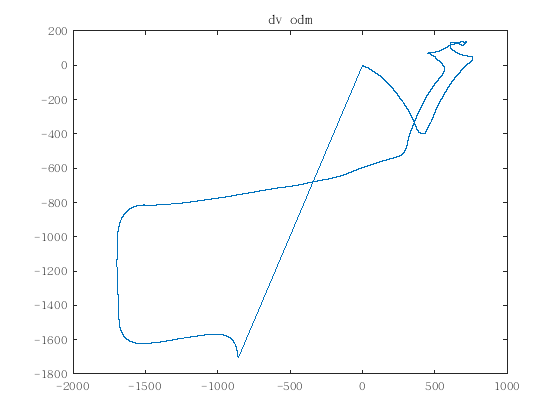

% dvx_imu在imu上先积分，然后在转换到世界坐标系
imu_pos=zeros(num,3);
vx=zeros(num,1);
vy=zeros(num,1);
vx_imu=zeros(num,1);
vy_imu=zeros(num,1);
for k=2:num-1
    theta=imu_pos(k-1,3)+dtheta(k);
    vx_imu(k)=vx_imu(k-1)+dvx_imu(k);
    vy_imu(k)=vy_imu(k-1)+dvy_imu(k);
    vx(k)=vx_imu(k)*cos(theta)-vy_imu(k)*sin(theta);
    vy(k)=vx_imu(k)*sin(theta)+vy_imu(k)*cos(theta);
    imu_pos_x=(vx(k-1)+vx(k))*dt(k)/2;
    imu_pos_y=(vy(k-1)+vy(k))*dt(k)/2;
    imu_pos(k,:)=imu_pos(k-1,:)+[imu_pos_x,imu_pos_y,dtheta(k)];
    
end
plot(imu_pos(:,1),imu_pos(:,2));
title("dv odm");

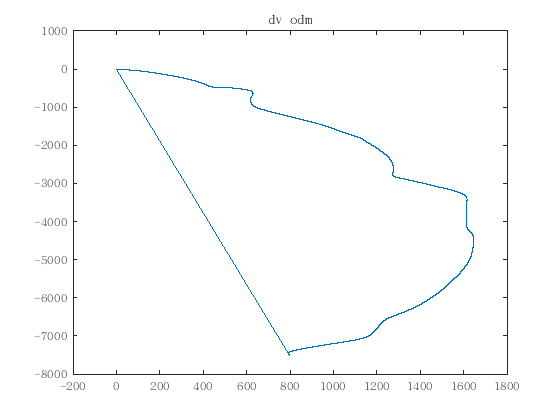

% dvx_imu 先转换到世界坐标系，然后在世界坐标系下进行速度积分
imu_pos=zeros(num,3);
vx=zeros(num,1);
vy=zeros(num,1);
vx_imu=zeros(num,1);
vy_imu=zeros(num,1);
for k=2:num-1
    theta=imu_pos(k-1,3)+dtheta(k);
    dvx=(dvx_imu(k)*cos(theta)-dvy_imu(k)*sin(theta));
    dvy=(dvx_imu(k)*sin(theta)+dvy_imu(k)*cos(theta));
    vx(k)=vx(k-1)+dvx;
    vy(k)=vy(k-1)+dvy;
    imu_pos_x=(vx(k)+vx(k-1))*dt(k)/2;
    imu_pos_y=(vy(k)+vy(k-1))*dt(k)/2;
    imu_pos(k,:)=imu_pos(k-1,:)+[imu_pos_x,imu_pos_y,dtheta(k)];
    
end
plot(imu_pos(:,1),imu_pos(:,2));
title("dv odm");


imu_pos=zeros(num,3);
vx=zeros(num,1);
vy=zeros(num,1);
vx_imu=zeros(num,1);
vy_imu=zeros(num,1);
for k=2:num-1
    theta=imu_pos(k-1,3)+dtheta(k);
    vx_imu(k)=vx_imu(k-1)+imudata_array(k,2)*dt(k);
    vy_imu(k)=vy_imu(k-1)+imudata_array(k,3)*dt(k);
    vx(k)=vx_imu(k)*cos(theta)-vy_imu(k)*sin(theta);
    vy(k)=vx_imu(k)*sin(theta)+vy_imu(k)*cos(theta);
    imu_pos_x=(vx(k-1)+vx(k))*dt(k)/2;
    imu_pos_y=(vy(k-1)+vy(k))*dt(k)/2;
    imu_pos(k,:)=imu_pos(k-1,:)+[imu_pos_x,imu_pos_y,dtheta(k)];
    
end
plot(imu_pos(:,1),imu_pos(:,2));
title("dv odm");

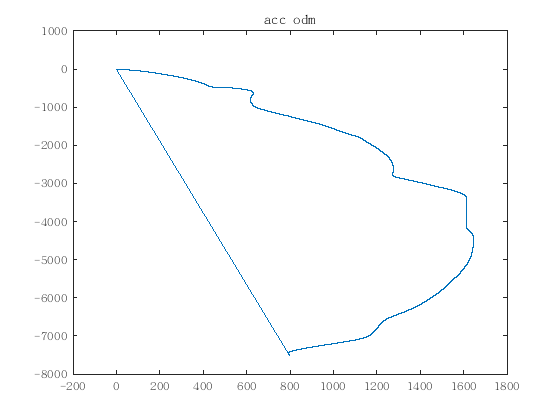

w_last=0;
vx_last=0;
vy_last=0;
ax_last=0;
ay_last=0;
pos=zeros(num,3);
for k=2:num-1
    dtheta_temp=(imudata_array(k,4)+w_last)*0.5*dt(k);
    ax=imudata_array(k,2)*cos(pos(k-1,3)+dtheta_temp)-imudata_array(k,3)*sin(pos(k-1,3)+dtheta_temp);
    ddx=vx_last*dt(k)+(ax+ax_last)*dt(k)^2/4;
    
    ay=imudata_array(k,2)*sin(pos(k-1,3)+dtheta_temp)+imudata_array(k,3)*cos(pos(k-1,3)+dtheta_temp);
    ddy=vy_last*dt(k)+(ay+ay_last)*dt(k)^2/4;
    
    % ax=ax_imu*cos(pos(3)+dtheta)+ay_imu*sin(pos(3)+dtheta);
    % ddx=vx_last*dt+(ax+ax_last)*dt^2/4;
    % 
    % ay=ax_imu*sin(pos(3)+dtheta)-ay_imu*cos(pos(3)+dtheta);
    % ddy=vy_last*dt+(ay+ay_last)*dt^2/4;
    
    vx_last=vx_last+(ax+ax_last)*dt(k)/2;
    vy_last=vy_last+(ay+ay_last)*dt(k)/2;
    ax_last=ax;
    ay_last=ay;
    w_last=imudata_array(k,4);
    pos(k,:)=pos(k-1,:)+[ddx,ddy,dtheta_temp];
end
plot(pos(:,1),pos(:,2));
title("acc odm");

nav_pos=zeros(num,2);
for j=1:num-1
    nav_pos_n=v_north(j)*dt(j);
    nav_pos_e=v_east(j)*dt(j);
    nav_pos(j+1,:)=nav_pos(j,:)+[nav_pos_e,nav_pos_n];
    
end
figure;plot(nav_pos(:,1),nav_pos(:,2),'DisplayName','out.pose');
title("ground truth");